# CRISPI-MS Delta V Calculations

clc
clear

## Uranus, Major Moons & Ring Parameters

% Uranus
mu_Uranus = 5.7940e+06; % Gravitational constant [km^3/s^2]
r_Uranus = 25559; % radius [km]
epsilon_Uranus = 0.02293; % eccentricity

% Oberon
r_ob = 761.4; % radius [km]
a_ob = 583.5e+03; % semi-major axis [km]
P_ob = 13.463234; % orbital period [days]
epsilon_ob = 0.0014; % eccentricity
r_ob_orb = a_ob*(1 + epsilon_ob); % radius of orbit [km] (come back and address elliptical)

% Titania
r_ti = 788.9; % radius [km]
a_ti = 436.30e+03; % semi-major axis [km]
P_ti = 8.705867; % orbital period [days]
epsilon_ti = 0.0011; % eccentricity
r_ti_orb = a_ti*(1 + epsilon_ti); % radius of orbit [km] (come back and address elliptical)

% Umbriel
r_umb = 584.7; % radius [km]
a_umb = 266.00e+03; % semi-major axis [km]
P_umb = 4.144176; % orbital period [days]
epsilon_umb = 0.0039; % eccentricity
r_umb_orb = a_umb*(1 + epsilon_umb); % radius of orbit [km] (come back and address elliptical)

% Ariel
r_ar = 581.1; % radius [km]
a_ar = 190.90e+03; % semi-major axis [km]
P_ar = 2.520379; % orbital period [days]
epsilon_ar = 0.0012; % eccentricity
r_ar_orb = a_ar*(1 + epsilon_ar); % radius of orbit [km] (come back and address elliptical)

% Miranda
r_mir = 240; % radius [km]
a_mir = 129.90e+03; % semi-major axis [km]
P_mir = 1.413479; % orbital period [days]
epsilon_mir = 0.0013; % eccentricity
r_mir_orb = a_mir*(1 + epsilon_mir); % radius of orbit [km] (come back and address elliptical)

% Mu Ring
r_mu =  97.7e+03; % radius [km] (simplification, refine later)

## UOP Post-Equatorialized Orbit (this is wrong rn)

% The following parameters were obtained from graphics presented in UOP
% mission concept documentation, and may not be accurate.

r_a = 1.6e+06; % apoapsis [km]
r_p = 1.4e+05; % periapsis [km]
a = (r_a + r_p)/2; % semi-major axis
epsilon = 1 - (r_p/a); % eccentricity
F = 0-2*(a-r_p); % second ellipse focus (for plotting)
%p = r_p*(1 + epsilon); % semilatus rectum


## Impulsive Tangential Burn Calculations

% Initial Elliptical Orbit to Moons
Initial_to_Oberon = CalculateDeltaV(r_a, r_ob_orb, r_p)

V_p_new = 8.1715

Initial_to_Oberon = 0.5527

Initial_to_Ariel = CalculateDeltaV(r_a, r_ar_orb, r_p)

V_p_new = 6.9120

Initial_to_Ariel = 1.8122

Initial_to_Miranda = CalculateDeltaV(r_a, r_mir_orb, r_p)

V_p_new = 6.3138

Initial_to_Miranda = 2.4104

Initial_to_Mu = CalculateDeltaV(r_a, r_mu, r_p)

V_p_new = 5.8327

Initial_to_Mu = 2.8915

Initial_to_Mirandao_updated = CalculateDeltaV(r_a, 155799, r_p)

V_p_new = 6.6027

Initial_to_Mirandao_updated = 2.1215


% Subsequent Ellipical Orbit Transfers
Ariel_to_Miranda = CalculateDeltaV(r_ar_orb, r_mir_orb, r_p)

V_p_new = 6.3138

Ariel_to_Miranda = 0.5982

Miranda_to_Mu = CalculateDeltaV(r_mir_orb, r_mu, r_p)

V_p_new = 5.8327

Miranda_to_Mu = 0.4810

Ariel_to_Mu = CalculateDeltaV(r_ar_orb, r_mu, r_p)

V_p_new = 5.8327

Ariel_to_Mu = 1.0793

## Trans-Satellite Injection Burns

% Impulsive burn calculation for going from elliptical UOP orbit to
% circular orbit about desired satellites

## Hohmann Transfer Calculations

## Plotting

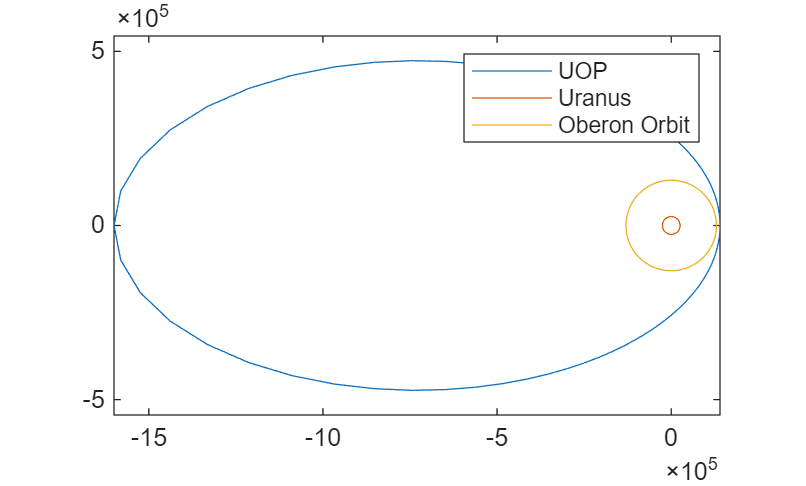

figure()
t = 0:pi/50:2*pi; % plotting interval

% UOP Post-Equatorialization Orbit
[x_UOP, y_UOP] = CalculateOrbit(1, a ,epsilon, r_Uranus);
plot(x_UOP, y_UOP)
axis equal
hold on

% Uranus
[x_Ur, y_Ur] = CalculateOrbit(0, a, 0, r_Uranus);
plot(x_Ur,y_Ur)

% Moon Orbits:
% Oberon
[x_ob, y_ob] = CalculateOrbit(1, a_ob, epsilon_ob, r_ob);
% plot(x_ob, y_ob)

% Titania
[x_ti, y_ti] = CalculateOrbit(1, a_ti, epsilon_ti, r_ti);
% plot(x_ti, y_ti)

% Umbriel
[x_umb, y_umb] = CalculateOrbit(1, a_umb, epsilon_umb, r_umb);
% plot(x_umb, y_umb)

% Ariel
[x_ar, y_ar] = CalculateOrbit(1, a_ar, epsilon_ar, r_ar);
% plot(x_ar, y_ar)

% Miranda
[x_mir, y_mir] = CalculateOrbit(1, a_mir, epsilon_mir, r_mir);
plot(x_mir, y_mir)

% Miranda elliptical
% [x_mir_elliptical, y__mir_elliptical] = CalculateOrbit(1, a_mir_elliptical,epsilon, r_Uranus);
% plot(x_UOP, y_UOP)

% Mu
[x_mu, y_mu] = CalculateOrbit(0, 0, 0, r_mu);
% plot(x_mu, y_mu)

% Oberon Elliptical


legend('UOP','Uranus','Oberon Orbit','Titania Orbit','Umbriel Orbit','Ariel Orbit','Miranda Orbit','Mu Ring Outer Range')

## Impulsive Apoapsis-Reducing Burn Function

function delta_v = CalculateDeltaV(r_a_init, r_a_final, r_p)
mu_Uranus = 5.7940e+06; % Gravitational constant [km^3/s^2]

% Old orbit
a_old = (r_a_init + r_p)/2;
eps_old = (r_a_init/a_old) - 1;
p_old = a_old*(1-eps_old^2);
H_old = sqrt(p_old*mu_Uranus);
V_p_old = H_old/r_p;

% New orbit
a_new = (r_a_final + r_p)/2;
eps_new = (r_a_final/a_new) - 1;
p_new = a_new*(1-eps_new^2);
H_new = sqrt(p_new*mu_Uranus);
V_p_new = H_new/r_p

delta_v = abs(V_p_old - V_p_new);
end


## Hohmann Transfer, Two-Burn Function

## Hohmann Transfer, Three-Burn Function

## Orbit Plotting Function

function [x_orb, y_orb] = CalculateOrbit(type, a, epsilon, r)

t = 0:pi/50:2*pi; % plotting interval

if type == 1
    x_orb = ((a*(1-epsilon^2))./(1+epsilon.*cos(t))).*cos(t);
    y_orb = ((a*(1-epsilon^2))./(1+epsilon.*cos(t))).*sin(t);
elseif type == 0
    x_orb = r.*cos(t);
    y_orb = r.*sin(t);

end
end